# Measuring a Flame Transfer Matrix

## 1. Before we start

Before proceeding we will `clear` the workspace and run the `dir` command to ensure that we are in the correct workspace. You should be able to see a folder named `tutorial_functions`. 

clear
dir
addpath(genpath('tutorial_functions'))

## 2. Introduction

In this tutorial we will learn how to obtain flame transfer matrices. A Flame Transfer Matrix (FTM) generalizes the concept of the Flame Transfer Function (FTF) by introducing more terms that show the coupling of the unsteady rate of heat release with all the acoustic variables. As with the FTFs, FTMs are widely used in low order models to study the response of the flame and its confinement to acoustic fluctuations. 

In the FTF formulation (see FTF tutorial) we used to have:


$$\frac{\hat{Q} }{\bar{Q} }=\textrm{FTF}\left(\omega \right)\frac{\hat{u_u } }{\bar{u} }\;\;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(1\right)$$


Then, through an energy balance upstream and downstream of the heat source we could relate $\hat{Q}$ (and thus $\hat{u}_u$) to the properties downstream, for instance $\hat{u}_d$. In the FTM approach we usually operate with matrices that relate all the upstream acoustic fluctuations, with all the downstream acoustic fluctuations, for example:


$$\left\lbrack \begin{array}{c}
\frac{\hat{p_d } }{\bar{\rho_d } \bar{c_d } }\\
\hat{u_d } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
T_{11}  & T_{12} \\
T_{21}  & T_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\hat{\frac{p_u }{\bar{\rho_u } \bar{c_u } }} \\
\hat{u_u } 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(2\right)$$


Somewhere within this matrix a term such as that in Eq. (1) exists, but the advantage of this formulation is that besides the FTF we also capture all the information about the balance of momentum and energy fluxes. This means that this approach can also account for losses in the system. 

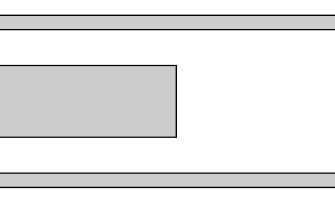            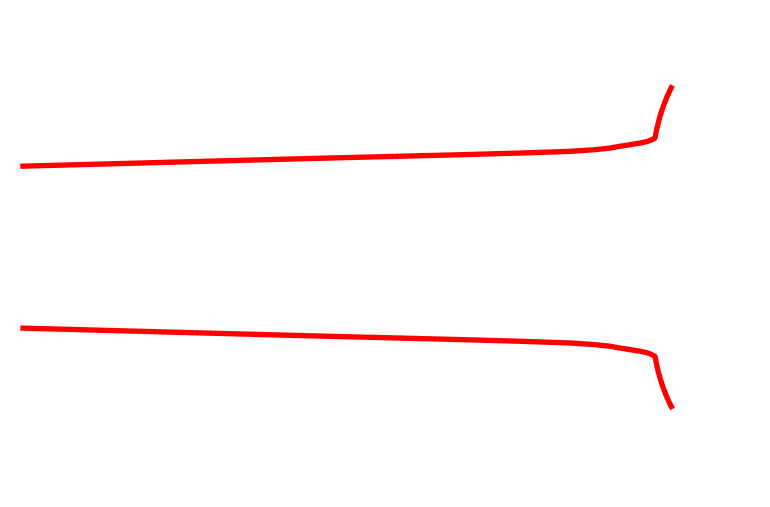

Fig. 1: In the FTM approach it is common to separate contributions from the burner geometry and the flame.

In the flame transfer matrix formulation, it is common to treat the contributions of the **burner geometry** and the contributions due to the **heat release** *separately *(Fig. 1). In this format we will have 2 transfer matrices:

- the **burner transfer matrix** $B$, 

- and the **flame transfer matrix** $F$. 

The transfer matrix for the full system is given by their multiplication:


$$\left\lbrack \begin{array}{cc}
T_{11}  & T_{12} \\
T_{21}  & T_{22} 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{cc}
B_{11}  & B_{12} \\
B_{21}  & B_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
F_{11}  & F_{12} \\
F_{21}  & F_{22} 
\end{array}\right\rbrack \;\;\;\;\;\textrm{Eq}\ldotp \left(3\right)$$


In this tutorial we will compute these transfer matrices for our model combustor:

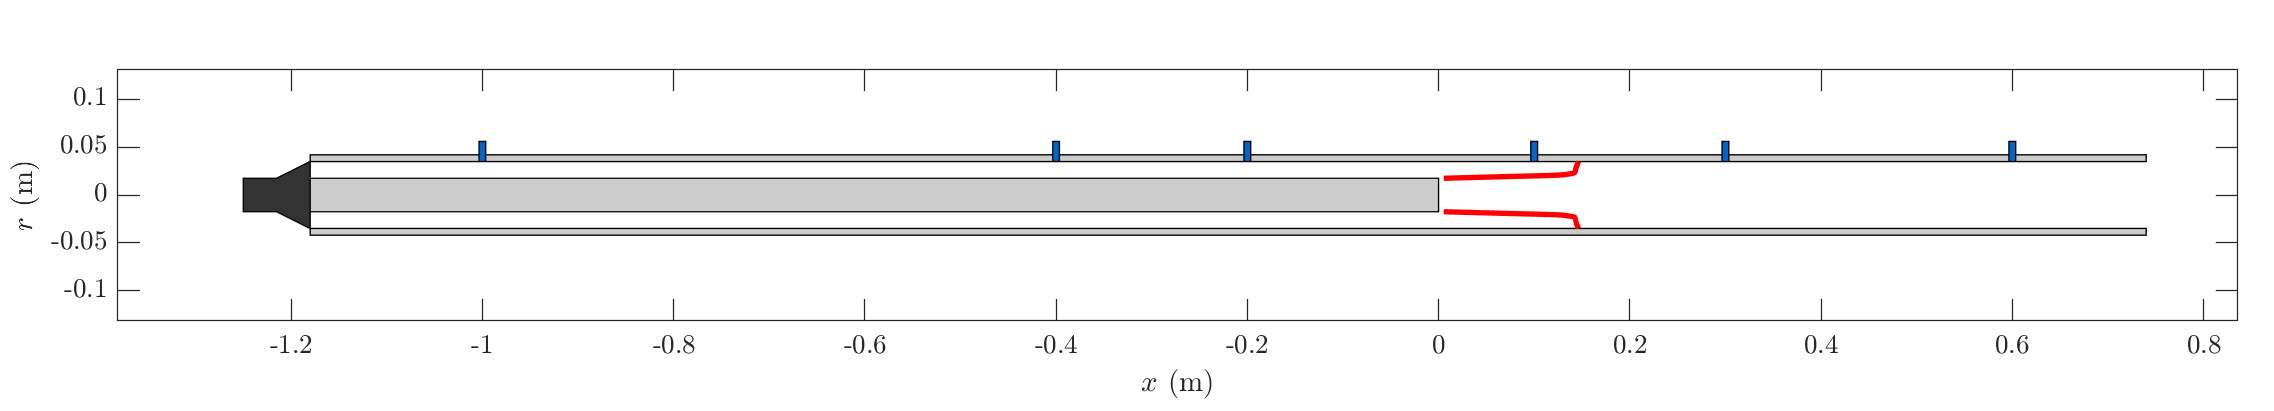

Fig. 2:  Schematic of the combustor.  

## 3. Burner Transfer Matrix

A burner transfer matrix is usually obtained in cold flow conditions. Therefore, to begin with, we will consider a combustor without a flame.  In the absence of heat release, the matrix $T$ in Eq. (3) is just the matrix $B$.  Now, you might have noticed that in Fig. 2 the combustor is equipped with microphones upstream and downstream of the flame holder. These will be used to obtain via the MMM the quantities: 

- $\hat{p}_u$ and  $\hat{u}_u$ which are computed at $x = 0^-$ (just before the area expansion), 

- $\hat{p}_d$ and $\hat{u}_d$, which are computed at $x = 0^+$ (just after the area expansion). 

According to Eq. (2) there will be 4 unknowns, i.e., the elements $B_{ij}$. By forcing the combustor upstream (as shown in Fig. 2) we will be able to obtain the values of $\hat{p}_u$,$\hat{u}_u$,$\hat{p}_d$ and $\hat{u}_d$. Plugging these into to Eq. (2), translates to a system of 2 equations with 4 unknowns. Therefore, to obtain the other 2 equations, in this tutorial we will force the combustor downstream of the flame holder.

**NB. **In a real experiment downstream forcing may not be possible, so instead one can change the exit boundary condition and consider this impedance in the computation of the transfer matrix.  

### a) Upstream Forcing

We begin by setting up the simulation. For the configuration shown in Fig. 2 we will assume that inlet of the configuration is **choked** (in experiments this type of boundary condition is useful to decouple the acoustics upstream of the combustor, i.e., fuel/oxidizer lines), and we will specify the velocity of the flow $\bar u_1$ and its temperature $\bar T_1$.  We will also assume that the outlet of the configuration is open to the atmosphere and specify the outlet pressure $\bar p_2$. Since it is a cold flow experiment, we will use $\bar Q = 0
$. Notice that we are using the subscripts 1 and 2 to denote the mean flow conditions before and after the area expansion at $x = 0$ respectively:

% Define inlet and outlet conditions:
u1 = 20;       % Inlet velocity (m/s)
T1 = 293;      % Inlet temperature (m/s)
p2 = 101300;   % Outlet pressure (Pa)
Qbar = 0;      % Heat release rate (W)

Next, we define the forcing and measurement conditions. Here we will force at a single frequency $f = 100$Hz, in later parts of the tutorial we will repeat this at different frequencies. 

% Define Forcing Conditions:
Forcing.Speaker = 'ON';
Forcing.Speaker_Downstream = 'OFF';
Forcing.Voltage = 0.5;   % (V)
Forcing.Frequency = 100; % (Hz)

% Sampling frequency: 
Measurement.Fs = 5000; % (Hz)
% Length of the measurements:
Measurement.Time = 2; % (s)

% Photomultiplier:
Measurement.PMT = 'OFF';
% Differential Microphones:
x_mic =  [-0.2,-0.4,-1,0.1,0.3,0.6]; % (m)
Measurement.Mic = 'ON';
Measurement.Mic_Pos  = x_mic;
% Hot wire anemometry:
x_hw = 0.2; % (m) 
Measurement.HWA = 'OFF';
Measurement.HWA_Pos = x_hw;

Now, let's look at the configuration

fn_plot_config(Forcing,Measurement)

Now run the simulation:

% Run the simulation
[Mean,Geom,Signals] = Run_Simulation(u1,T1,p2,Qbar,Forcing,Measurement);

Let's take a quick glance at the signals:

% Plot signals
zoom_in_time_steps = 100; 
fn_plot_Signals(Signals,Measurement,zoom_in_time_steps)

- Did you notice that one of the microphones is very close to a pressure antinode? You can see that the magnitude of the microphone at $x = -1$m is much smaller compared to the rest of the microphones. 

Now using the same codes developed in the MMM tutorial, we will reconstruct the acoustic field in each side of the flame holder and then propagate the signals towards $x = 0$.  

To achieve that, we first need to adapt our structures so that they can be passed to the functions:

% Adapting structures:
S_up = Signals;
S_dn = Signals;
M_up = Measurement;
M_dn = Measurement;
% Keep only relevant Microphones:
S_up.P_mic = S_up.P_mic(1:3,:);
S_dn.P_mic = S_dn.P_mic(4:6,:);
M_up.Mic_Pos = M_up.Mic_Pos(1:3);
M_dn.Mic_Pos = M_dn.Mic_Pos(4:6);

Now we perform the MMM:

% Multi-Microphone-Method:
[Fu,Gu,~] = fn_MMM(Mean,S_up,M_up);
[Fd,Gd,omega] = fn_MMM(Mean,S_dn,M_dn);
% Signal Reconstruction:
xu = 0;     % Position just before the flame holder
xd = 1e-5;  % Position just after the flame holder
[ph_u_uf,uh_u_uf] = fn_acoustic_field(Mean,Fu,Gu,omega,xu);
[ph_d_uf,uh_d_uf] = fn_acoustic_field(Mean,Fd,Gd,omega,xd);

Let's plot the acoustic field for 

fig = figure;
fn_plot_acoustic_field(Geom,Mean,Fu,Gu,Fd,Gd,omega,'k')

Can you spot:

- The discontinuity in the velocity fluctuations?

- The pressure node next to one of our microphones?

### b) Downstream Forcing

We will repeat the same process but now with downstream forcing.  So, we will begin by setting that up:

Forcing.Speaker = 'OFF';
Forcing.Speaker_Downstream = 'ON';

Let's preview the configuration:

figure
fn_plot_config(Forcing,Measurement)

Now run the simulation:

[Mean,Geom,Signals,Sim] = Run_Simulation(u1,T1,p2,Qbar,Forcing,Measurement);

In a similar fashion as before we will first take a quick glance at the signals:

% Plot signals
zoom_in_time_steps = 100; 
fn_plot_Signals(Signals,Measurement,zoom_in_time_steps)

Even though all the signals are much weaker, this time none of the microphones is situated next to a pressure node. We can say that because they all oscillate at the same order of magnitude. 

**NB**. The signals are much weaker despite using the same voltage. This is because of the way the code is set up. In practice every speaker might have a different transfer function so this might emulate that. The only thing to keep in mind is that you need a forcing level that is higher than the background noise, but not strong enough to induce nonlinearities in the acoustics. (Here we don't have background noise, so we can go as low as we need). 

Now we proceed to perform the MMM and reconstruct the acoustic field:

% Adapting structures:
S_up = Signals;
S_dn = Signals;
M_up = Measurement;
M_dn = Measurement;
% Keep only relevant Microphones:
S_up.P_mic = S_up.P_mic(1:3,:);
S_dn.P_mic = S_dn.P_mic(4:6,:);
M_up.Mic_Pos = M_up.Mic_Pos(1:3);
M_dn.Mic_Pos = M_dn.Mic_Pos(4:6);
% Multi-Microphone-Method:
[Fu,Gu,~] = fn_MMM(Mean,S_up,M_up);
[Fd,Gd,omega] = fn_MMM(Mean,S_dn,M_dn);
% Signal Reconstruction:
xu = 0;     % Position just before the flame holder
xd = 1e-5;  % Position just after the flame holder
[ph_u_df,uh_u_df] = fn_acoustic_field(Mean,Fu,Gu,omega,xu);
[ph_d_df,uh_d_df] = fn_acoustic_field(Mean,Fd,Gd,omega,xd);

Now we are going to plot the "new" acoustic field on top of the previous one. Since the amplitudes are normalized you will be able to see the differences between forcing upstream and downstream:

figure(fig)
fn_plot_acoustic_field(Geom,Mean,Fu,Gu,Fd,Gd,omega,'r')
legend('Upstream','Downstream')

In black we have the results for upstream forcing, in red the results for downstream forcing. Recall that the boundary conditions of the combustor are choked at the inlet and open end at the outlet. 

- A choked inlet sets the velocity fluctuations close to zero. From this figure we can see that, as expected this only occurs when we force downstream. 

- An open end sets the fluctuations in pressure to zero. Again, we can see that this only happens when we force upstream.

When we force a configuration through the boundaries, we are essentially overriding the boundary condition.

### c) Computing the transfer matrix

Now that we have all the elements, we can easily compute the burner transfer matrix. To achieve that we first rearrange Eq. (2) such that:


$$\left\lbrack \begin{array}{c}
\frac{{\hat{p_d } }^{\textrm{uf}} }{\bar{\rho_d } \bar{c_d } }\\
{\hat{u_d } }^{\textrm{uf}} \\
\frac{{\hat{p_d } }^{\textrm{df}} }{\bar{\rho_d } \bar{c_d } }\\
{\hat{u_d } }^{\textrm{df}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\frac{{\hat{p_u } }^{\textrm{uf}} }{\bar{\rho_u } \bar{c_u } } & {\hat{{\;u}_u } }^{\textrm{uf}}  & 0 & 0\\
0 & 0 & \frac{{\hat{p_u } }^{\textrm{uf}} }{\bar{\rho_u } \bar{c_u } } & {\hat{{\;u}_u } }^{\textrm{uf}} \\
\frac{{\hat{p_u } }^{\textrm{df}} }{\bar{\rho_u } \bar{c_u } } & {\hat{{\;u}_u } }^{\textrm{df}}  & 0 & 0\\
0 & 0 & \frac{{\hat{p_u } }^{\textrm{df}} }{\bar{\rho_u } \bar{c_u } } & {\hat{{\;u}_u } }^{\textrm{df}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
B_{11} \\
B_{12} \\
B_{21} \\
B_{22} 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(4\right)$$


**Task**:

- Using Eq. (4) finish the function fn_BTM and compute the matrix $B$.

[B] =  fn_BTM(Mean, ph_d_uf, uh_d_uf, ph_d_df, uh_d_df, ph_u_uf, uh_u_uf, ph_u_df, uh_u_df)

If done accurately, you must get approximately the following values:


$$B\approx \left\lbrack \begin{array}{cc}
1 & 0\ldotp 02\\
0 & 0\ldotp 75
\end{array}\right\rbrack$$


This value of the transfer matrix is valid only for a frequency $\omega = 2\pi f$, with$f = 100$Hz. Now repeat the process for other frequencies.  Keep the number $N$ small, we will plot the results of this loop over previously computed curves of this model. 

N = 4; % Number of points
freqs = linspace(50,400,N);
[B11,B12,B21,B22] = fn_BTM_loop(u1,T1,p2,Qbar,Forcing,Measurement,freqs);
figure
fn_plot_BTM(freqs, B11, B12, B21, B22,'BTM');

The burner transfer matrix reveals some important aspects of the combustor. 

- The $B_{11}$ element is very close to 1, which means that pressure is almost continuous across the area expansion, $\hat{p}_d \approx \hat{p_u}$.

- The $B_{12}$ element is small, but not zero, indicating that there are some pressure losses in the system. 

- The $B_{21}$ element is almost zero everywhere.

- The $B_{22}$ element is approximately 0.75 everywhere, this is related to the area expansion.

### d) The L - Zeta model

Many configurations can be accurately modeled with the $L - \zeta$ model:


$$\left\lbrack \begin{array}{c}
\hat{\frac{p_d }{\bar{\rho_d } \bar{c_d } }} \\
\hat{u_d } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{\bar{\rho_u } \bar{c_u } }{\bar{\rho_d } \bar{c_d } } & \frac{\bar{\rho_u } \bar{c_u } }{\bar{\rho_d } \bar{c_d } }\left(-i\omega \frac{L_{\textrm{eq}} }{\bar{c_u } }-\bar{M_u } \zeta \right)\\
0 & \frac{A_1 }{A_2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\frac{\hat{p_u } }{\bar{\rho_u } \bar{c_u } }\\
\hat{u_u } 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(5\right)$$


Here $L_{eq}$ is the effective length of the area jump, $\bar{M}_u$ is the Mach number, and $\zeta$ is a pressure loss coefficient.  See reference [1] for a derivation, which uses the unsteady Bernoulli equation. Given the values obtained in the previous section we can see that our burner indeed follows the trends of this model. Usually computing $L_{eq}$ and $\zeta$from the geometry is not an easy task, and thus it is common to obtain them by fitting. 

[1]  Schuermans, BBH, Polifke, W, & Paschereit, CO. "Modeling Transfer  Matrices of Premixed Flames and Comparison With Experimental Results." *Proceedings of the ASME 1999 * Indianapolis, Indiana, USA. June 7–10, 1999. V002T02A024. ASME. [https://doi.org/10.1115/99-GT-132](https://doi.org/10.1115/99-GT-132)

**Task**

- Finish the function `fn_LZmodel` and compute the elements $B_{11}$, $L_{eq}$, $\zeta$, $B_{22}$ according to Eq. (5).

[B11,B22,Leq,Zeta] = fn_LZmodel(Mean,Geom)

- How do the values $B_{11}$ and $B_{22}$ compare to those observed above?

Now let's compare the $B_{21}$ with the one obtained via the $L-\zeta$ model:

fn_plot_LZmodel(Mean,Leq,Zeta)

Depending on the fitting procedure the results may vary. I got a value of  $L_{eq}$ close to 0 which is indeed the case since we have an abrupt expansion. I also obtained a value of $\zeta = -0.34$ , which gives an indication of the pressure lost in the system. We can compare this value with the rough approximation given by:


$$\zeta =2\frac{\bar{p_u } -\bar{p_d } }{\bar{\rho_u } {\bar{u_u } }^2 }$$


p1 = Mean.p1;
p2 = Mean.p2;
u1 = Mean.u1;
rho1 = Mean.rho1;
Z_model = 2*(p1 - p2)/(rho1*u1^2)

The value is very close to the one obtained by the fitting procedure! We have now fully determined the burner transfer matrix and fitted it to the $L-\zeta$model. The next step is to compute the Flame transfer matrix.

## 4. Flame Transfer Matrix

To compute the FTM we will turn on the heat release in the system to $\bar{Q} = 100$kw and repeat the exact same process as before. The only difference is that this time since the flame is on, we will be computing the total transfer matrix $T$ in Eq. (2). Given that we already know the matrix $B$ computing the matrix $F$ is simple:


$$B^{-1} T=F\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(6\right)$$


Qbar = 100000; %(W)
freqs = 100; % Hz
[T11,T12,T21,T22] = fn_BTM_loop(u1,T1,p2,Qbar,Forcing,Measurement,freqs);
T = [T11 T12; T21 T22];
% Flame transfer Matrix:
F = inv(B)*T

- Can you see the difference in the values for the matrix? 

By repeating the same process with different frequencies, we obtain the following FTM:

figure
[freqs,F22] = fn_plot_BTM(freqs, F(1,1), F(1,2), F(2,1), F(2,2),'FTM_1');

A few interesting patterns appear:

- The $F_{11}$ element is constant with a value of 2.45.

- The $F_{12}$ element has some modulations around a mean value of approximately 0.31. These modulations decay with increasing frequency.

- The $F_{21}$ element has an approximately constant gain with a value of 0.4 and the phase appears to also be constant at a value of $\pm \pi$, which translates to a value of -0.4.

- The $F_{22}$ element has a high gain at low frequencies and then it decays towards 1 at higher frequencies. The gain presents modulations as well. 

### a) The Rankine-Hugoniot relations

Flame models can be conveniently modelled with the Rankine Hugoniot relations [1], which are derived from conservation of mass, momentum, and energy fluxes across a heat source. Since our combustor operates with a low Mach number, we can neglect terms of high er orders in the Mach number, then the conditions for pressure and velocity become:


$$\begin{array}{l}
\hat{p_d } =\hat{p_u } -\left(\frac{\bar{T_d } }{\bar{T_u } }-1\right)\bar{\rho_u } {\bar{u_u } }^2 \left(\frac{\hat{u_u } }{\bar{u_u } }+\hat{\frac{Q}{\bar{Q} }} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(7a\right)\;\;\\
\hat{u_d } =\hat{u_u } +\left(\frac{\bar{T_d } }{\bar{T_u } }-1\right)\bar{u_u } \left(\hat{\frac{Q}{\bar{Q} }} -\frac{\hat{p_u } }{\bar{p_u } }\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Eq}\ldotp \left(7b\right)
\end{array}$$


[1]  Schuermans, BBH, Polifke, W, & Paschereit, CO. "Modeling Transfer  Matrices of Premixed Flames and Comparison With Experimental Results." *Proceedings of the ASME 1999 * Indianapolis, Indiana, USA. June 7–10, 1999. V002T02A024. ASME. [https://doi.org/10.1115/99-GT-132](https://doi.org/10.1115/99-GT-132)

Substituting the heat release $\hat{Q}/\bar{Q}$ with the expression given in Eq. (1) and arranging it in matrix form we obtain:


$$\left\lbrack \begin{array}{c}
\hat{\frac{p_d }{\bar{\rho_d } \bar{c_d } }} \\
\hat{u_d } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{\bar{\rho_u } \bar{c_u } }{\bar{\rho_d } \bar{c_d } } & \frac{\bar{\rho_u } \bar{u_u } }{\bar{\rho_d } \bar{c_d } }\left(1-\frac{\bar{T_d } }{\bar{T_u } }\right)\left(1+\textrm{FTF}\right)\\
\left(1-\frac{\bar{T_d } }{\bar{T_u } }\right)\gamma \bar{M_u }  & 1+\left(\frac{\bar{T_d } }{\bar{T_u } }-1\right)\textrm{FTF}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\frac{\hat{p_u } }{\bar{\rho_u } \bar{c_u } }\\
\hat{u_u } 
\end{array}\right\rbrack \;\;\;\;\;\textrm{Eq}\ldotp \left(8\right)$$


The matrix given in Eq. (8) reveals some important aspects. So let's compute the mean values and compare.

**Task**

- Finish the function `fn_FTM` and compare the values obtained in the FTM vs those via the Rankine Hugoniot conditions. 

Qbar = 100000; %(W)
Mean = fn_mean_flow(u1,T1,p2,Qbar,Geom); 
[F11,F21,FTF] = fn_FTM(Mean,F22);
F11
F21

If done accurately $F_{11}$ should be close to 2.45 and element $F_{21}$ should be close to -0.4. These are the same values we discussed above. In the last step we will compare the FTF obtained via the FTM and the FTF of the analytic model of the flame. 

figure
fn_plot_FTF(freqs,FTF,Mean,Geom)

If done properly the two curves should lie on top of each other! (Except for the discrepancies observed at high frequencies due to spatial discretization of the flame.)

### b) Effects of Temperature

From Eq. (8) we observed that temperature can modify substantially our Flame Transfer Matrix.  For this purpose, we will re-run the entire simulation but with a lower temperature. This can be achieved by lowering the equivalence ratios to leaner values. In our model this will be achieved by using $\bar{Q} = 50$ kW. This time we will skip the simulation and just plot the new data over the previous data set. 

figure
[freqs,F22] = fn_plot_BTM([], [], [], [], [],'FTM_2');
fn_plot_BTM([], [], [], [], [],'FTM_1');
subplot(4,2,1)
legend('Q = 50 kW','Q = 100 kW')

Now let's compare the values obtained with those from the Rankine Hugoniot conditions:

Qbar = 50000; % (W)
Mean = fn_mean_flow(u1,T1,p2,Qbar,Geom); 
[F11,F21,FTF_50] = fn_FTM(Mean,F22);
F11
F21

- How do these values compare to those observed in the FTM?

- How about the FTF do you expect to see any changes?

figure
fn_plot_FTF(freqs,FTF_50,Mean,Geom)
subplot(2,1,1)
hold on
plot(freqs,abs(FTF),'x')
legend('Measured Q = 50 kW','Analytical 50 kW', 'Measured Q = 100 kW')
subplot(2,1,2)
hold on
plot(freqs,unwrap(angle(FTF)),'x')

You should be able to see that the difference is barely noticeable**. The reason behind this is that the FTF for this "V" flame has a very weak dependence on the mean flow.  Its FTF is given by:


$$\textrm{FTF}\left(\Omega \right)=\frac{\;2}{i\Omega \left(a+b\right)}\;\left(a-b\;\exp \left(-i\;\Omega \right)+\frac{\left(b-a\right)\;}{i\;\Omega }\left(1-\exp \left(i\;\Omega \right)\right)\right)$$


where


$$\Omega =\frac{\omega \left(b-a\right)}{S_u \sqrt{1-{\left(\frac{S_u }{\bar{u} }\right)}^2 }}$$


Here $S_u$ is the laminar flame speed, $a$ and $b$ are the flame holder radius and the duct radius. Usually $S_u \ll \bar{u}$ (as in out case) so the denominator in the last equation is almost equal to $S_u$, therefore the mean flow dependency is very weak. 

** The jump in phase at about 320 Hz, is because it was not unwrapped properly. 